% error analysis on describing functions
% step 1: what are the higher order fourier coeffs?
% see notebook p94-95

% i = harmonic (1 is fundamental)
% N = saturation level
% k = slope of non-saturated signal
% a = amplitude of input sinusoid
clear all
syms i real integer positive 
syms N a k wt real positive
%syms sat(x)
%sat(x) = piecewise(abs(x)<1, x, sign(x)*1);
unsat_integrand = sin(wt)*k*a/N * sin(i * wt);
wt_s = asin(N/(a*k));

bi = 2*N/pi * ( int(unsat_integrand,wt, 0, wt_s) + ...
                int(sin(i*wt),wt, wt_s, pi-wt_s) + ...
                int(unsat_integrand,wt, pi-wt_s, pi));
Keq = simplify(bi / a)

$$Keq = \begin{array}{l} \left\{ \begin{array}{cl} \frac{2\,N\,\sigma_{1}+2\,a^{2}\,k^{2}\,\sigma_{2}}{\sigma_{5}} & \text{ if }i=1\\ \frac{\left(N\,\cos\left(i\,\sigma_{2}\right)-i\,\sin\left(i\,\sigma_{2}\right)\,\sigma_{1}\right)\,\left(2\,{\left(-1\right)}^{i}-2\right)}{a\,i\,\pi \,\left(i^{2}-1\right)} & \text{ if }i\neq 1\\ -\frac{N\,\sigma_{1}-\pi \,a^{2}\,k^{2}}{\sigma_{5}} & \text{ if }\sigma_{2}=\frac{\pi }{2}\wedge i=1\\ \frac{i\,k\,\left(\pi \,i^{2}-\pi +4\,\cos\left(\frac{\pi \,i}{2}\right)\,\sigma_{3}\,\sigma_{4}\right)}{2\,\pi \,\sigma_{3}\,\sigma_{4}\,\left(i-1\right)\,\left(i+1\right)} & \text{ if }\sigma_{2}=\frac{\pi }{2}\wedge i\neq 1\\ 0 & \text{ if }\sigma_{2}=\frac{\pi }{2}\wedge 2\leq i\wedge i\in \left\{2\,l+1|l\in \mathbb{Z}\right\} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\sqrt{a^{2}\,k^{2}-N^{2}}\\ \sigma_{2}=\mathrm{asin}\left(\frac{N}{a\,k}\right)\\ \sigma_{3}=\Gamma (\frac{3}{2}-\frac{i}{2})\\ \sigma_{4}=\Gamma (\frac{i}{2}+\frac{3}{2})\\ \sigma_{5}=a^{2}\,k\,\pi \end{array}$$

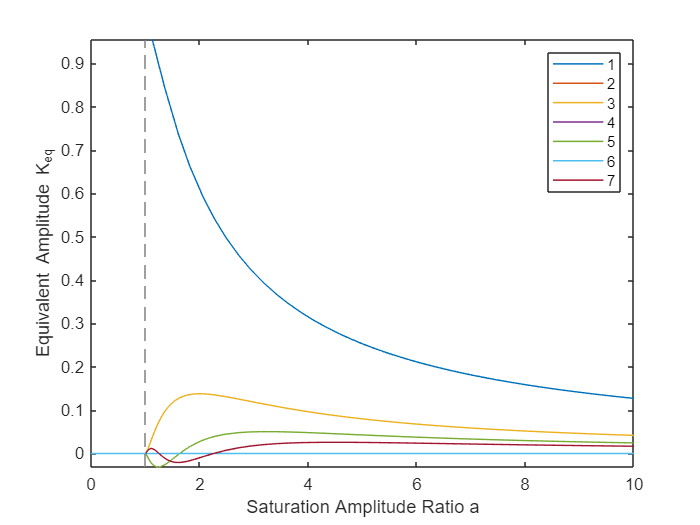


harmonics = 1:7;
for ii=harmonics
    Ki(ii) = simplify(subs(Keq,i,ii));
end

Ki = subs(Ki, [N,k],[1,1]);
% Keq plot
fplot(Ki,[0,10])
xlabel('Saturation Amplitude Ratio a')
ylabel('Equivalent Amplitude K_{eq}')
legend(strsplit(num2str(harmonics)))

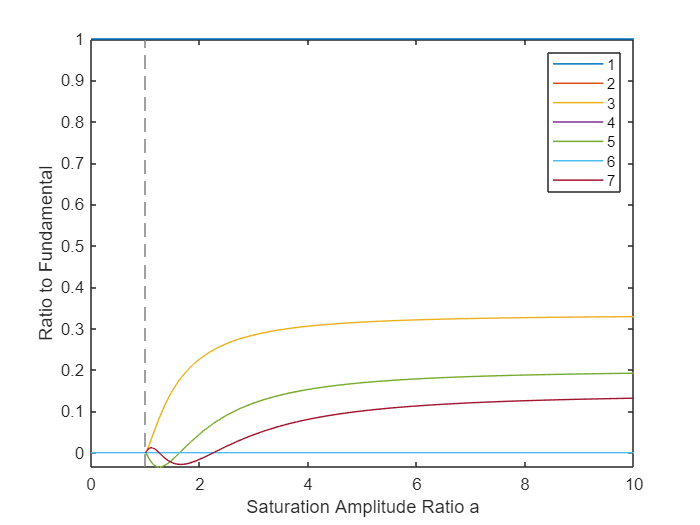


% Keq/Keq(1) plot (comparison of harmonics to fundamental)
fplot(Ki/Ki(1),[0,10])
xlabel('Saturation Amplitude Ratio a')
ylabel('Ratio to Fundamental')
legend(strsplit(num2str(harmonics)))

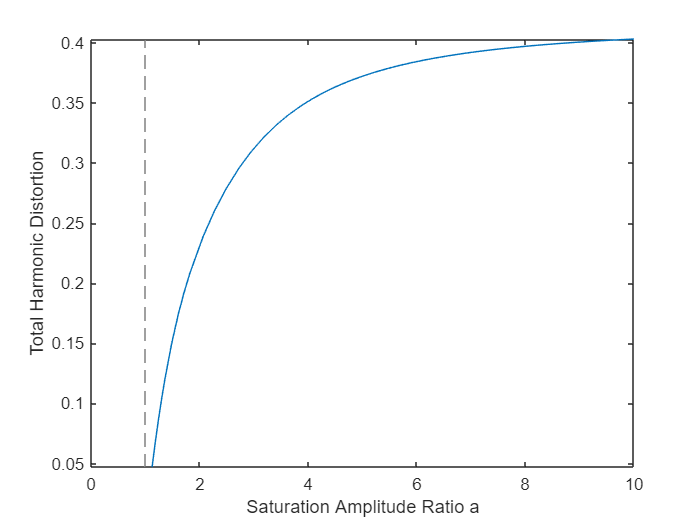


% total harmonic distortion plot
% if enough harmonics, should asymptote to 48.3% (square wave)
fplot(sqrt(sum(Ki(2:end).^2))/Ki(1),[0 10])
xlabel('Saturation Amplitude Ratio a')
ylabel('Total Harmonic Distortion')



% step 2: what is their effect on energy and body amplitude?


